## Name:

## Date:

## PID: 

## Quiz 4 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

**Submission Instructions:** Quiz files should be titled Quiz_X_FirstNameLastName, Ex: Quiz_4_AsadMirza. To convert the MLX file into a PDF go to the Export icon under Live Editor and select "Export to PDF".

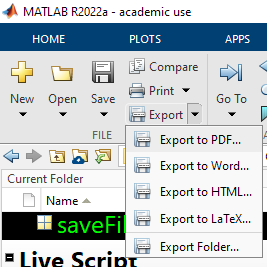

Any scratch paper used should have your name, date, and PID on it and be submitted to me when you finish your quiz.

Question 1 (20%) 

a) (10%) Solve the following ordinary differential equation using Backward Euler’s Method.

$\frac{\textrm{dy}}{\textrm{dt}}=2\,-9\,t^2$ , y(0) = 1

from t=0 to t=2 using a step size of h=0.1

clear,clc,close all
% Set up
y0 = 1;         % Initial condition
h = .1;         % Step size
t = 0:h:2;      % Time vector
y = zeros(1,length(t));     % Preallocate memory
y(1) = y0;              % Apply IC
f=@(t,y) 2 - 9*t^2;      % Set up function
for ii=1:length(t)-1
    y(ii+1) = fzero(@(Y) y(ii) + (f(t(ii+1),Y))*h - Y, y(ii));
end

b) (5%) Plot against the real solution of:


$$y=2t-3t^3 +1$$


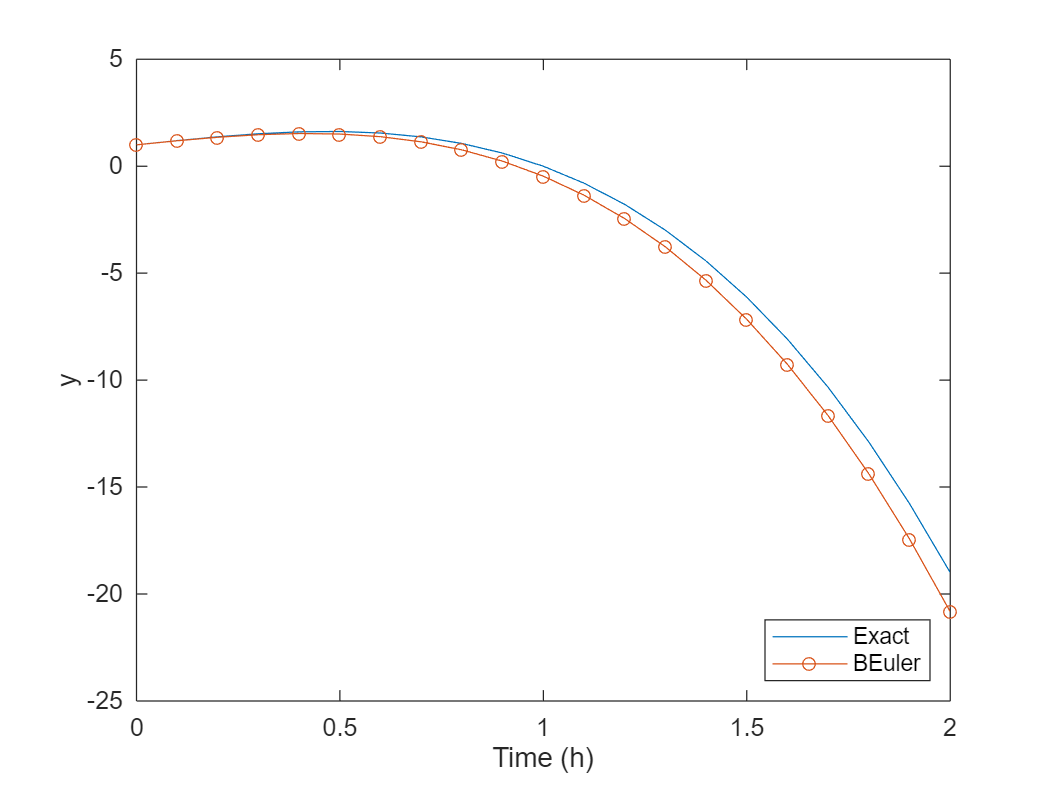

%Plotting
y_exact=@(t) 2.*t-3.*t.^3+1;
figure
plot(t,y_exact(t)) % Exact solution
hold on
plot(t,y,'-o','markersize',5) % Backward Euler
hold off
ylabel("y");
xlabel("Time (h)");
legend('Exact','BEuler',"Location","southeast")

c) (5%) Show the absolute error of the above approximation at y(1).

ind= find(t==1);
abs(y_exact(1)-y(ind))

ans = 0.4650

Question 2 (40%) 

For the function:


$$\frac{\textrm{dy}}{\textrm{dx}}=\frac{y}{4}-\frac{y^2 }{20},\;y\left(0\right)=1$$


The real integral solution is:


$$y=\frac{5e^{\frac{x}{4}} }{e^{\frac{x}{4}} +4}$$


Do the following with a step size of $h=2$

a) (20%) Solve using the Forward Euler Method and plot it and the real solution from x = 0 to 10.

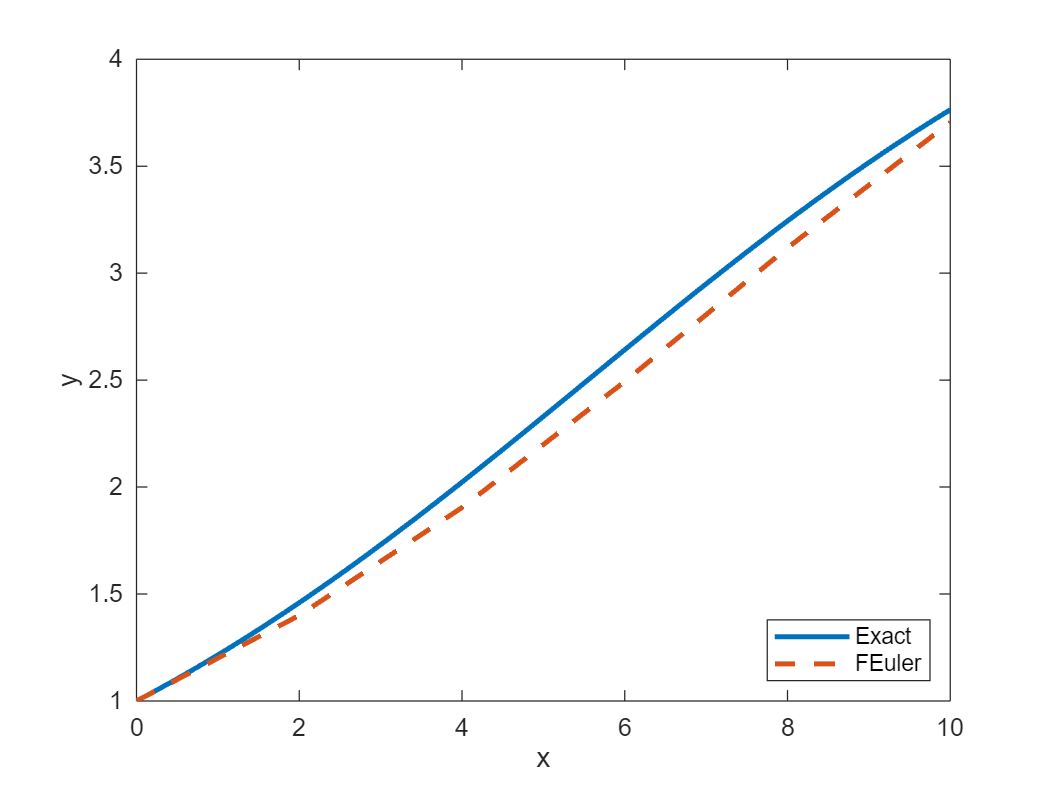

clear,clc,close all
% Set up parameters
y0 = 1;              % Initial condition
h = 2;             % Step size
x = 0:h:10;           % Time vector
% Preallocate memory
t = zeros(1,length(x));  % Solution vector
t(1) = y0;           % Set initial condition
% Forward Euler method
for ii = 1:length(x)-1
    t(ii+1) = t(ii) + (t(ii)/4 -t(ii).^2/20) * h;
end
% Plot the results
figure;
% Exact solution for comparison
xx = linspace(0, 10);
y_exact = 5*exp(xx/4)./(exp(xx/4)+4);
plot(xx, y_exact,'LineWidth', 2);     % Plot exact solution
hold on;
plot(x, t,'--','LineWidth', 2);           % Plot Forward Euler solution
hold off;
legend('Exact','FEuler',"Location","southeast")
xlabel('x')
ylabel('y')

b) (20%) Solve using the Central Euler Method and plot it and the real solution from x = 0 to 10.

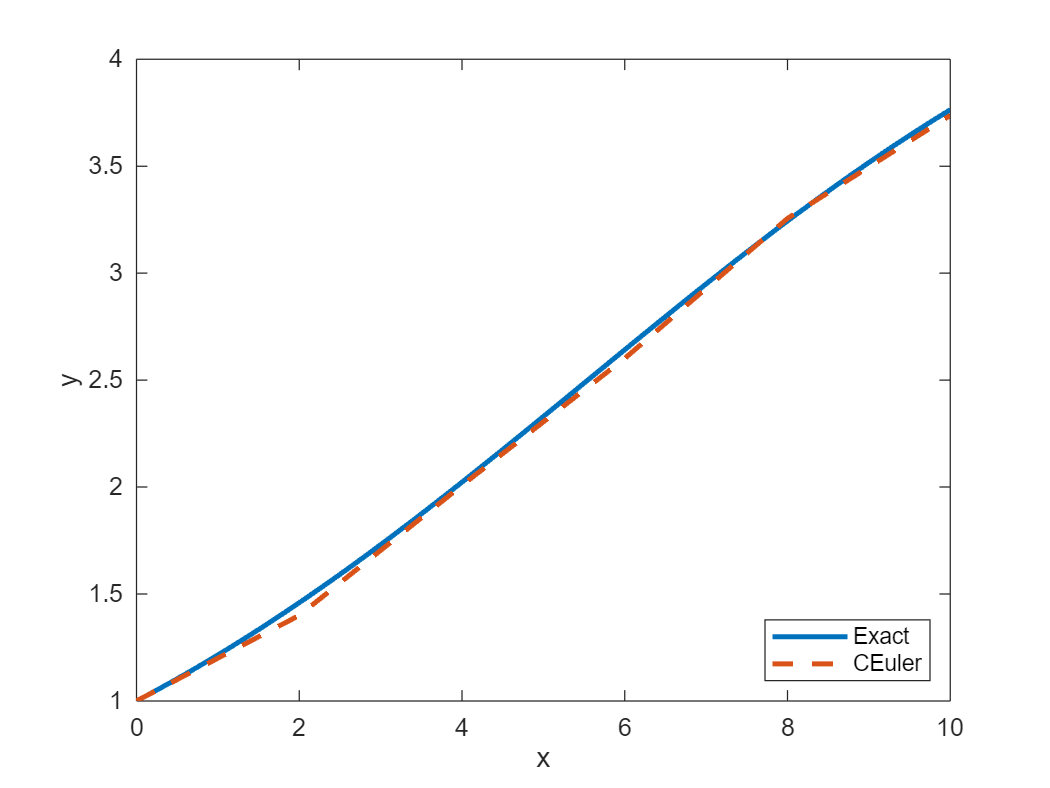

% Set up, use same step size and time vector from before
% Preallocate memory for the numerical solution
t = zeros(1,length(x));  % Solution vector
t(1) = y0;                % Set initial condition
% Use forward Euler to calculate the second point y(2) (for central difference)
t(2) = t(1) + h * (t(1)/4 -t(1).^2/20);
% Implement Central Difference Method for the rest of the points
for ii = 2:length(x)-1
    t(ii+1) = t(ii-1) + 2 * h * (t(ii)/4 -t(ii).^2/20);  % Central difference update
end
% Exact solution for comparison, reuse function from before
% Plot the results
figure;
plot(xx, y_exact,'LineWidth', 2);     % Plot exact solution
hold on;
plot(x, t,'--', 'LineWidth', 2);           % Plot Central Euler solution
hold off;
legend('Exact','CEuler',"Location","southeast")
xlabel('x')
ylabel('y')

Question 3 (40%) 

A newly planted forest plant biomass will be constantly changing between different stages. Most will reside as living trees, but eventually they die from age and other events. The dead trees will eventually decay and fall and be converted into humus. 

A typical yearly biological model is:


$$x^{\prime } =-3x\left(t\right)+\;6z\left(t\right)$$



$$y^{\prime } =-2y\left(t\right)+3x\left(t\right)$$



$$z^{\prime } =-6z\left(t\right)+2y\left(t\right)$$


Where $x$ is the amount living trees biomass and $y$ is the amount of dead trees biomass and $z$ is the humus biomass.

a) (30%) If we have no dead trees or humus at the start planting, plot the coupled system with 1500 initially planted trees during 6 years.

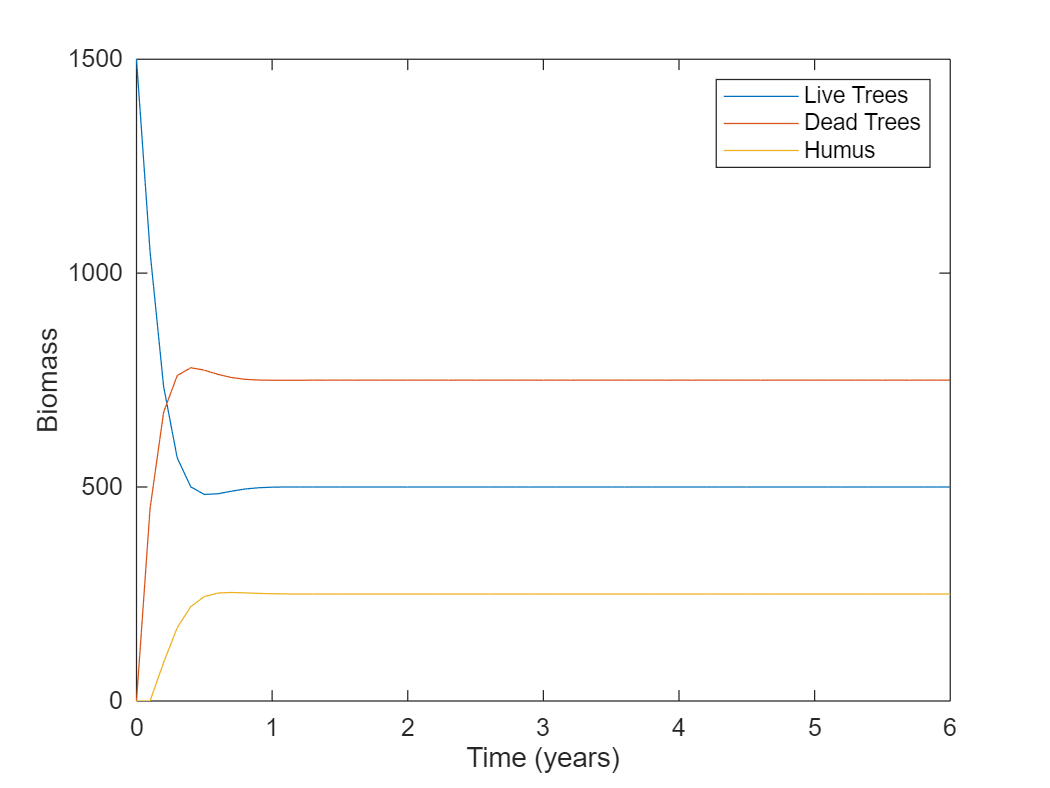

% Option 1: Simulate biomass dynamics using separate variables

% Initial conditions
P0trees = 1500;   % Initial live tree biomass
P0dead = 0;       % Initial dead tree biomass
P0humus = 0;     % Initial hummus (decomposed organic matter)

h = 0.1;          % Time step (1/10th of a year)
t = 0:h:6;        % Time period (6 years total)

% Pre-allocate arrays to store biomass over time and seed with initial conditions
Ptrees = zeros(1, length(t));   % Array for live trees biomass
Ptrees(1) = P0trees;       % Set initial live tree biomass
Pdead = zeros(1, length(t));    % Array for dead trees biomass
Pdead(1) = P0dead;         % Set initial dead tree biomass
Phumus = zeros(1, length(t));  % Array for humus biomass
Phumus(1) = P0humus;     % Set initial humus biomass

% Define the coupled ODE system for biomass changes
dPtress = @(x1, x2, x3) -3*x1 + 6*x3; % Rate of change for live trees
dPdead = @(x1, x2, x3) 3*x1 - 2*x2;   % Rate of change for dead trees
dPhummus = @(x1, x2, x3) 2*x2 - 6*x3; % Rate of change for humus

% Simulate the system using the forward Euler method
for k = 1:length(t)-1
    % Update live tree biomass
    Ptrees(k+1) = Ptrees(k) + h*dPtress(Ptrees(k), Pdead(k), Phumus(k));
    % Update dead tree biomass
    Pdead(k+1) = Pdead(k) + h*dPdead(Ptrees(k), Pdead(k), Phumus(k));
    % Update humus biomass
    Phumus(k+1) = Phumus(k) + h*dPhummus(Ptrees(k), Pdead(k), Phumus(k));
end

% Plot the results
figure
plot(t, Ptrees, t, Pdead, t, Phumus) % Plot all biomass types
xlabel('Time (years)')
ylabel('Biomass')
legend('Live Trees', 'Dead Trees', 'Humus', 'Location', 'northeast')


% Option 2: Simulate biomass dynamics using a matrix approach

% Set up the time step and time vector
h = 0.1;           % Time step (1/10th of a year)
t = 0:h:6;         % Time period (6 years)

% Initial biomass values (live trees, dead trees, hummus)
Biomass = [1500; 0; 0];   % Column vector for initial biomass states

% Define the coupled ODE system using a function handle
f = @(x) [-3*x(1) + 6*x(3);  % Change in live trees
          3*x(1) - 2*x(2);   % Change in dead trees
          2*x(2) - 6*x(3)];  % Change in humus

% Use forward Euler method to update biomass over time
for k = 1:length(t)-1
    Biomass(:, k+1) = Biomass(:, k) + h*f(Biomass(:, k)); % Update biomass
end

% Plot the results
figure
plot(t, Biomass(1, :), t, Biomass(2, :), t, Biomass(3, :)) % Plot all biomass types
xlabel('Time (years)')
ylabel('Biomass')
legend('Live Trees', 'Dead Trees', 'Humus', 'Location', 'northeast')

b) (10%) At the end of the 6 years what is the amount of biomass for live trees,dead trees, and humus?

fprintf('The amount of living biomass is %3.2f\n', Ptrees(end))

The amount of living biomass is 500.00


fprintf('The amount of dead biomass is %3.2f\n', Pdead(end))

The amount of dead biomass is 750.00


fprintf('The amount of humus biomass is %3.2f\n', Phumus(end))

The amount of humus biomass is 250.00
